# Dimensionality reduction

The training examples in "split.mat" contains 31 features:

clear all;
load('split.mat', 'train_examples');

Use Principal Components Analysis to investigate reducing the dimensionality of the resulting feature space.

Marks are available for:

- Applying appropriate pre-processing steps to the data [4 marks]

- Recovering the principal components, and the transformed data [4 marks]

- Taking sensible steps to decide on how many principle components to retain [6 marks]

- Creating the new lower-dimensional dataset [2 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

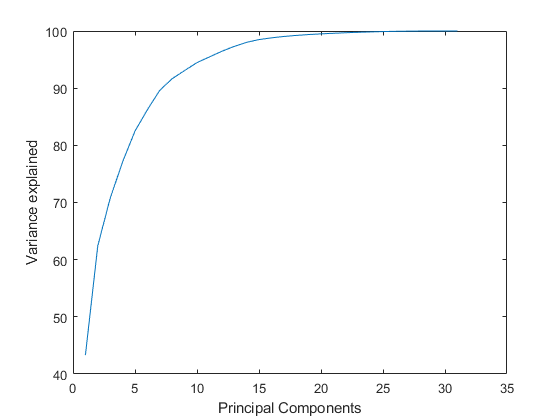

% start of standarization process:
% calculate the mean of all the training examples:
m.mean = mean(train_examples{:,:});   
% calculate the satndard deviation of all the training examples:
m.std = std(train_examples{:,:});

% for each value in training examples:
for i=1:size(train_examples,1)
    % subtract the mean from the current example:
    train_examples{i,:} = train_examples{i,:} - m.mean;
    % divide the current example that has had the mean
    % substracted by the standard deviation:
    train_examples{i,:} = train_examples{i,:} ./ m.std;
end
% end of standardisation process

% convert the train examples table into a matrix:
train_examples = train_examples{:,:};

% perform pca on the data:
[principal_components, data_transformed,~,~,explained] = pca(train_examples);

% plot the cumulative sum of explained:
% this lets you see how much of the total variance in the original dataset you are 
% preserving:
plot(cumsum(explained));
xlabel("Principal Components")
ylabel("Variance explained")


% using datacursor on my graph, i will use the first 11 PCs in order
% to explain at least a 95% variance in my training data. This
% significantly decreases the dimensionality of the dataset.

data_reduced = data_transformed(:, 1:1:11)

data_reduced =    -4.0097   -0.2995    2.0384   -1.6528   -0.0916    0.4727   -0.2972    0.5191    1.0597    0.5266    0.2735
   -2.2568   -0.8900   -1.2828   -1.5597   -1.5101    0.2363   -0.0638   -0.1173    0.0550   -0.0608   -0.1642
    1.6919    6.5463    2.0244   -0.2795   -0.9937    0.7312   -0.0070    0.3270   -0.9737   -0.0932   -0.9648
   -3.1542   -2.0070    0.2118    1.8112    0.1212   -0.3519   -0.2105   -0.2294   -0.2635   -0.6784   -0.4617
   -0.8637    0.9836   -1.0266   -1.0183    0.5251    1.1585    0.1636   -0.4723    1.0643   -0.2973    0.9147
   -1.3871    0.1266    1.4652   -1.0578   -2.7269   -0.6340   -0.6221   -0.6741   -0.1152    0.1356   -0.1264
    2.2148    0.2288    1.0205    1.4038    0.8805   -1.5353   -0.4221   -0.2737    0.6936   -0.8630    0.6553
   -2.0501    0.0323   -0.1853   -1.9339   -1.0379   -0.4491    0.6294    0.2374    0.3201    0.0161   -0.0992
   11.1796   -4.1493   -0.7147   -2.2996    0.6842    0.3283   -0.7091    0.2714    1.0124    1.3